# **Section 1.3 Edge Detection**

Edge detection is defined as identifying points in an image that has massive discontinuities, texture changes, and brightness changes. Images that have one of these three characteristics are typically edges of a surface on an image. For this project I chose to attempt Canny Edge detection - created by John Canny who decided upon creating a smoothing filter that would best fit the criteria of detection. He attempted and showed that first order derivatives of Gaussian functions would approximate his desired ideal filter accurately. There are general criteria for an optimal edge detection that John Canny hoped to fulfill. As with anything, a process with a low error rate was needed, the edge detector had to be accurate to be useful. To steer away from a redundant process, any edge in an image should be calculated once, where noise should not create inaccurate, or even false edges. To do this, it is stated that John Canny used the calculus of variations, using functionals - which can be defined as a linear mapping of a vector space.

There are multiple steps to create a Canny Edge detector, each will be mentioned in detail as the code progresses.

**1.1 Applying a Gaussian filter**

Out of curiosity I sought to create a Gaussian Filter in two ways using a built in function, and calculating it manually via code - The method of calculating the Gaussian filter is below:

close
clear all
clc
original_image = imread('boop.jpg'); %Colormap is empty because its RGB 
original_image = rgb2gray(original_image);
mask_size = 3; %Size of Gaussian Mask - N x N
sigma = 2; %This value was decided upon arbitrarily

First the image was loaded using the imread(..) function, using the path of the file as a parameter. The image is then converted to greyscale(2d) as the conv2(..) function in matlab could not compute 3D vectors. I decided upon creating a 3x3 filter creating a variable mask_size, with a sigma value (standard deviation) of 2 to apply the intensity of blur.

%Gaussian Mask
%The scaling is done by first generating all Gaussian coefficients, then
%summing up all the coefficients, and dividing the element by this sum -
%this ensures that the area underneath the gaussian is always 1;
index = -floor(mask_size/2) : floor(mask_size/2);%Rounding the NxN gaussian mask's range down
%toward infinity
[X Y] = meshgrid(index, index); %This function generates 2d coordinates
%The important aspect of this function is that it creates spatial
%coordinates that will be the same size as the mask desired. For odd values
%of N, the spatial coordinates will be symmetric.

The Gaussian Mask must first go under preparation to be scaled. The indecis are first created using the mask_size, creating a vector of the same length, spread equally along positive and negative portions. To do this accurately, the NxN mask's range was rounded downwards towards infinity. The matlab function meshgrid(..) was then used to correctly generate 2d spatial coordinates, it is important for these to be generated with the same size of the mask desired. Another good reason on why the classic algorithm uses a 5x5 matrix for the mask is to create symmetric spatial coordinates. The mask is then calculated using the Gaussian function below:


$$G(x,y) = \frac{1}{2 \pi \sigma ^{2}} e^{- \frac{x^{2} + y^{2}}{2 \sigma ^{2}}}$$


generated_mask = exp(-(X.^2 + Y.^2) / (2*sigma*sigma));
%Normalizing the generated mask, so the total area is 1
generated_mask_normalized = generated_mask / sum(generated_mask(:));
generated_mask_column = generated_mask_normalized(:);%Method of creating a column vector
%Filtering should start here

This mask is then to be scaled down to have an area of 1 by summing all the values, and dividing each index by the sum as seen by the variable generated_mask_normalized above. This is then converted to a column vector to simplify calculation in the later parts.

%Filtering should start here
%The image is converted to class type double, for higher precision
original_image_double_precision = im2double(original_image);
%We need to pad the array in order to properly filter the image, if the 
%border of the image is not padded, the spatial mask will not filter pixels
%beyond the image pixels.
padded_array = padarray(original_image_double_precision, [floor(mask_size/2) floor(mask_size/2)]);

The filtering portion of the code starts here, as the image is converted to type double for higher precision, the array is then padded on the edges to properly filter the image, as if this is not done the spatial mask will not filter the uneven amount of pixels that border the image.

%im2col will take distinct pixels around one pixel - the size of the
%gaussian mask since we have a column vector - converting the surrounding
%pixels into columns, and creating a matrix of pixel groups NxN
columns = im2col(padded_array, [mask_size mask_size], 'sliding');
%We have come to the point where we must sum over the rows for each column,
%this multiplication is done by a built in function bsxfun
pixel_group_filter = sum(bsxfun(@times, columns, generated_mask_column), 1);
output_image = col2im(pixel_group_filter, [mask_size mask_size], size(padded_array), 'sliding');

As the mask is 3x3, the center pixel always has a surrounding set of pixels around it, as the mask is a column vector, the surrounding pixels are converted into columns, creating a matrix of pixels of size NxN in this case, of size 3. At this point the pixel filter is summed using the matlab functio bsxfun() where the rows for each matrix is summed over every column to apply the filter, Once this is done, the surrounding pixels are then converted back to their original position to output the filtered image.

This can also be done much simpler using a built in matlab function, fspecial taking in the mask size, and sigma value to create the filter, and apply it using the the imfilter function

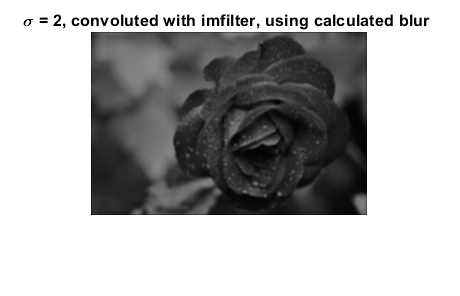

%# Filter it - The Filter can also being created using built in matlab functions
G = fspecial('gaussian',[3 3],2);

image_meth1 = imfilter(original_image,G,'same');
imshow(image_meth1)
title(['\sigma = 2, convoluted with imfilter, using calculated blur ']);

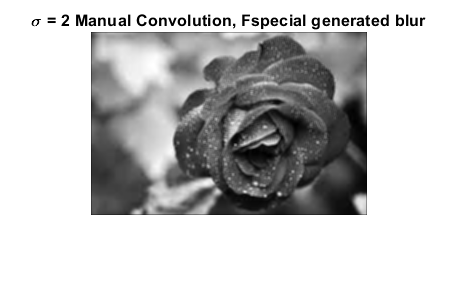

%Method 2 - convolving
convolution = conv2(original_image,G, 'same');
imshow(convolution, []);
title('\sigma = 2 Manual Convolution, Fspecial generated blur');

image_meth2 = convolution;

The normal method of applying the filter is done via convolution using the conv2(..) command, using this method requires the image to be in greyscale, the image can then be output. There are subtle differences between the methods, however for this project I went with the manual convolution using the conv2() command, and the second method of creating the gaussian filter using the fspecial comand, as the image generated was brighter.

#### 1.2 Finding the intensity gradients

Reading up on this topic, there are multiple ways to find the Intensity gradients. Method 1 - A simple way using a built in method is seen below to calculate Gx and Gy.

%%Calculating Gradient - Method 1
[Gx,Gy] = gradient(G);   

I attempted to do the same using John Canny's method - calculate the intensity gradients using the first order derivative of the Gaussian function this method is built to match the any kernal size.

%%Method 2 Calculating Gradient
%This can be calculated using the first order derivative of the gaussian
%The kernal must be the same size 
epsilon=1e-2;
halfsize=ceil(sigma*sqrt(-2*log(sqrt(2*pi)*sigma*epsilon)));
size=2*halfsize+1;
for i=1:size
    for j=1:size
        u=[i-halfsize-1 j-halfsize-1];
        hx(i,j)=normrnd(u(1),sigma)*normrnd(u(2),sigma);
    end
end
hx=hx/sqrt(sum(sum(abs(hx).*abs(hx))));
hy=hx';

The size, and halfsize is calculated, and the value for epsilon used is stored. An embedded for loop is then used to calculate each gradiet using the first order derivative as well as the gaussian function, this results in value hx for the horizontal gradients, and hy for vertical gradients, which is the transpose of hx.

X = conv2(image_meth2, hx, 'same');
Y = conv2(image_meth2, hy, 'same');
wiki_eq_direction = atan2 (X, Y);
wiki_eq_direction = wiki_eq_direction*180/pi;

Above, the calculated x and Y filters are applied, and preparation for finding the actual directions begins. According to the wikipedia page, Edges are rounded to one of four angles, 0, 45, 90, or 135. Any angle that lays in between these values are rounded down to 0. An attempt for doing this is below: 

for i = 1  : 183
    for j = 1 : 276
        if ((wiki_eq_direction(i, j) > 0 ) && (wiki_eq_direction(i, j) < 0) || (wiki_eq_direction(i, j) > 157.5) && (wiki_eq_direction(i, j) < -157.5))
            directions(i, j) = 0;
        end
        
        if ((wiki_eq_direction(i, j) > 22.5) && (wiki_eq_direction(i, j) < 45) || (wiki_eq_direction(i, j) < -112.5) && (wiki_eq_direction(i, j) > -157.5))
            directions(i, j) = 45;
        end
        
        if ((wiki_eq_direction(i, j) > 67.5 && wiki_eq_direction(i, j) < 90) || (wiki_eq_direction(i, j) < -67.5 && wiki_eq_direction(i, j) > 112.5))
            directions(i, j) = 90;
        end
        
        if ((wiki_eq_direction(i, j) > 112.5 && wiki_eq_direction(i, j) <= 135) || (wiki_eq_direction(i, j) < -22.5 && wiki_eq_direction(i, j) > -67.5))
            directions(i, j) = 135;
        end
    end
end

The code is an embedded for loop to go through every value of the array, as the image maintains 183x276 pixels. The value at every point in the array is assessed to implement edge detection, if the value sits on one of the four directions,it is kept, however if it lays between these values it is rounded down to zero.

# Experiment and Results

Unfortunately I was not able to complete all 5 steps of the Canny Edge detector. i did get up complete applying a Gaussian blur using two methods, finding the intensity gradients using two methods, and starting the beginning of the detection of edges using angles in the image. Although I was not successful I did attempt to go as far as I could in the experiment, not succeeding in Hysterisis, Supression or thresholding, but I did learn some vaiuable information regarding the functions of matlab, as well as image processing.